2/122

ans = 0.0164

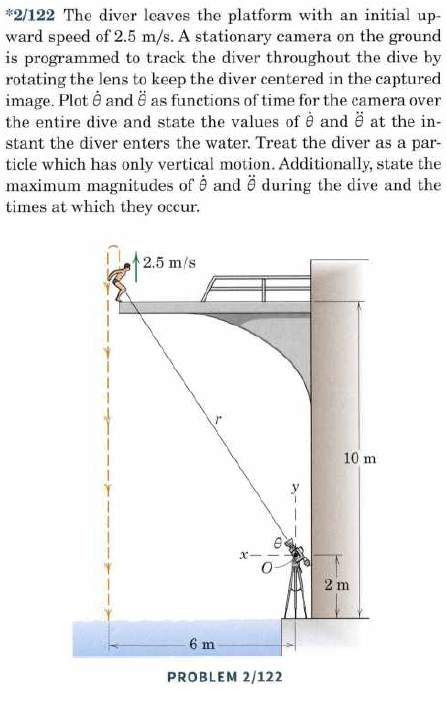

clear all
v_0 = 2.5

v_0 = 2.5000

a_0 = -9.81

a_0 = -9.8100

x_0 = 6

x_0 = 6

y_0 = 8

y_0 = 8

syms t
v(t) = v_0 + a_0 * t

$$v(t) = \frac{5}{2}-\frac{981\,t}{100}$$

y(t) =  int(v(t), t) + y_0

$$y(t) = 8-\frac{t\,\left(981\,t-500\right)}{200}$$

t_vand = vpa(solve(-2 == y(t), t), 8);
t_vand = vpa(t_vand(2), 8)

$$t\_vand = 1.705249$$

r(t) = sqrt(x_0^2 + (y(t))^2)

$$r(t) = \sqrt{{\left(\frac{t\,\left(981\,t-500\right)}{200}-8\right)}^{2}+36}$$

r_dot(t) = diff(r(t), t)

$$r\_dot(t) = \frac{\left(\frac{981\,t}{100}-\frac{5}{2}\right)\,\left(\frac{t\,\left(981\,t-500\right)}{200}-8\right)}{\sqrt{{\left(\frac{t\,\left(981\,t-500\right)}{200}-8\right)}^{2}+36}}$$

theta(t) = atan(y(t)/x_0)

$$theta(t) = -\mathrm{atan}\left(\frac{t\,\left(981\,t-500\right)}{1200}-\frac{4}{3}\right)$$

v_theta(t) = v(t) * cos(theta(t))

$$v\_theta(t) = -\frac{\frac{981\,t}{100}-\frac{5}{2}}{\sqrt{{\left(\frac{t\,\left(981\,t-500\right)}{1200}-\frac{4}{3}\right)}^{2}+1}}$$

theta_dot(t) = v_theta(t) / r(t)

$$theta\_dot(t) = -\frac{\frac{981\,t}{100}-\frac{5}{2}}{\sqrt{{\left(\frac{t\,\left(981\,t-500\right)}{200}-8\right)}^{2}+36}\,\sqrt{{\left(\frac{t\,\left(981\,t-500\right)}{1200}-\frac{4}{3}\right)}^{2}+1}}$$

theta_dot(t_vand)

$$ans = -2.134273881206439541040780434609$$

theta_dot_deg = vpa(rad2deg(theta_dot(t_vand)),5)

$$theta\_dot\_deg = -122.28$$

For accelerationen

a_theta(t) = a_0 * cos(theta(t))

$$a\_theta(t) = -\frac{981}{100\,\sqrt{{\left(\frac{t\,\left(981\,t-500\right)}{1200}-\frac{4}{3}\right)}^{2}+1}}$$

theta_ddot(t) = diff(theta_dot(t), t) %(a_theta - 2 * r_dot(t) * theta_dot(t))/r(t)

$$theta\_ddot(t) = \begin{array}{l} \frac{{\sigma_{3}}^{2}\,\sigma_{2}}{{\left({\sigma_{2}}^{2}+36\right)}^{3/2}\,\sqrt{{\sigma_{1}}^{2}+1}}-\frac{981}{100\,\sqrt{{\sigma_{2}}^{2}+36}\,\sqrt{{\sigma_{1}}^{2}+1}}+\frac{\left(\frac{327\,t}{200}-\frac{5}{12}\right)\,\sigma_{3}\,\sigma_{1}}{\sqrt{{\sigma_{2}}^{2}+36}\,{\left({\sigma_{1}}^{2}+1\right)}^{3/2}}\\ \mathrm{where}\\ \sigma_{1}=\frac{t\,\left(981\,t-500\right)}{1200}-\frac{4}{3}\\ \sigma_{2}=\frac{t\,\left(981\,t-500\right)}{200}-8\\ \sigma_{3}=\frac{981\,t}{100}-\frac{5}{2} \end{array}$$

theta_ddot(t_vand)

$$ans = 1.5652500000000022985794764833322$$

theta_ddot_deg = vpa(rad2deg(theta_ddot(t_vand)),5)

$$theta\_ddot\_deg = 89.682$$

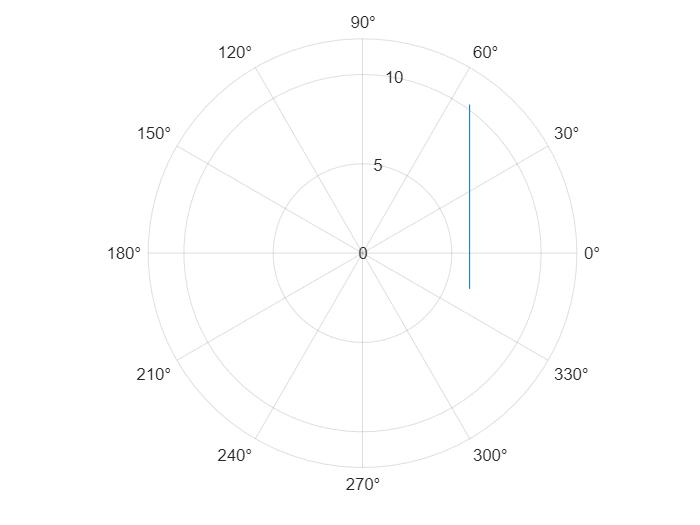

t_lin = linspace(0,t_vand,100);
polarplot(theta(t_lin), r(t_lin))

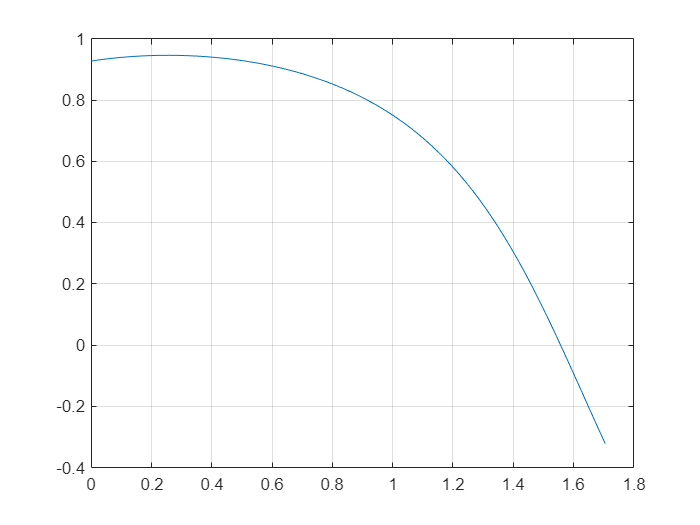

figure(1)
plot(t_lin, theta(t_lin))
grid("on")

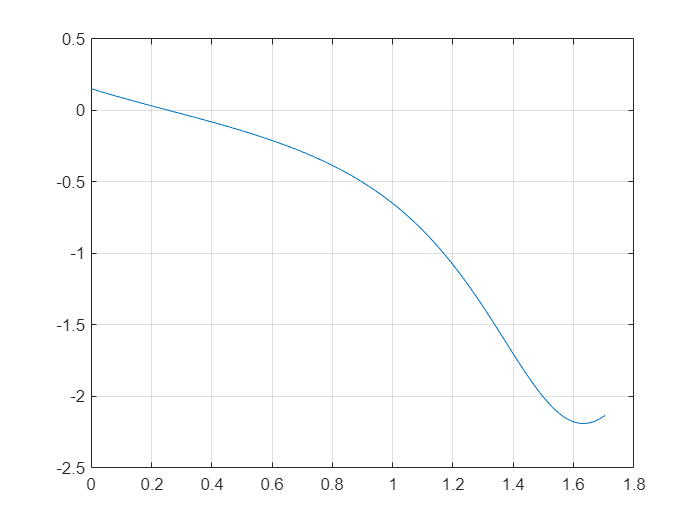

figure(2)
plot(t_lin, theta_dot(t_lin))
grid("on")

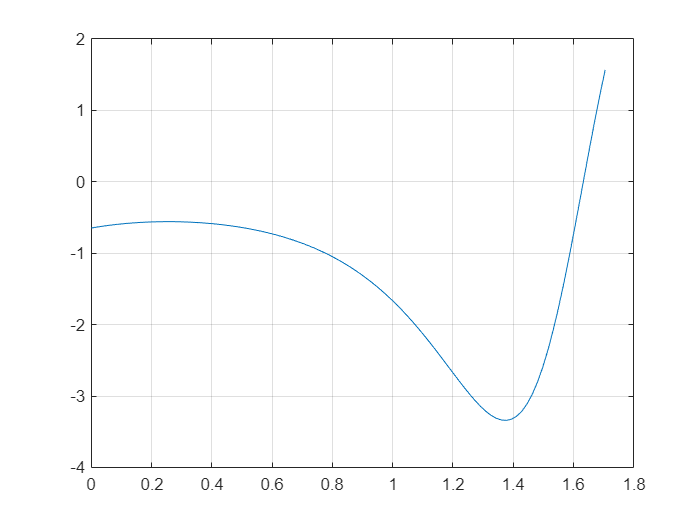

figure(3)
plot(t_lin, theta_ddot(t_lin))
grid("on")

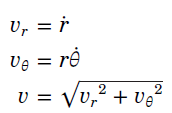

2/126

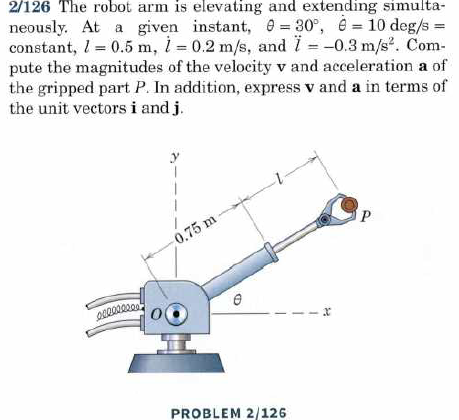

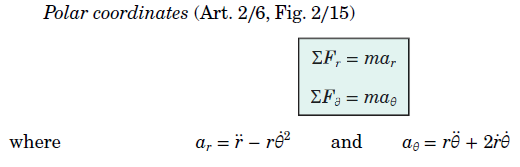

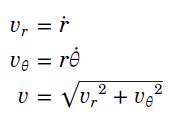

clear all
theta = deg2rad(30);
theta_dot = deg2rad(10);
theta_ddot = 0;
l = 0.5;
l_dot = 0.2;
l_ddot = -0.3;

r = 0.5 + 0.75;
r_dot = l_dot;
r_ddot = l_ddot;


v_theta = r * theta_dot

v_theta = 0.2182

v_r = r_dot

v_r = 0.2000

v = sqrt(v_theta^2 + v_r^2)

v = 0.2960


v_i =  v_r* cos(theta) - v_theta* sin(theta)

v_i = 0.0641

v_j =  v_r* sin(theta) + v_theta* cos(theta)

v_j = 0.2889


v_y = v *  sin(theta)

v_y = 0.1480

v = [v_i;v_y]

v =     0.0641
    0.1480


a_theta = r * theta_ddot + 2 * r_dot * theta_dot

a_theta = 0.0698

a_r = r_ddot - r * theta_dot^2

a_r = -0.3381

a = sqrt(a_theta^2 + a_r^2)

a = 0.3452

a_i = a_r* cos(theta) - a_theta* sin(theta)

a_i = -0.3277

a_y = a_r* sin(theta) + a_theta* cos(theta)

a_y = -0.1086

a = [a_i;a_y]

a =    -0.3277
   -0.1086
